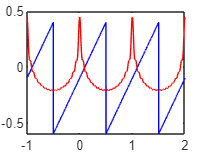

T0 = 1; w0 = 2*pi/T0;
Ts = 0.0005; t = -1:Ts:2;
x = t - 0.1 - round(t);

N = 15;
ak = fsAnalysis(x, t, T0, Ts, N);
Ak = abs(ak(N+2:end));
a0 = ak(N+1);
ksi0 = 0;
ksi = angle(abs(ak(N+2:end)));
y = a0 * ones(size(t));

    for k = 1 : N
        y = y + Ak(k) * cos(k*w0*t + ksi(k));
    end

plot(t, x, 'b', t, y, 'r');